# Software Defined Radio

## SDR Transmitter

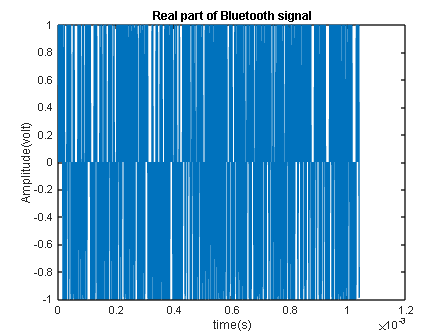

%Generate Bluetooth Low Energy (BLE) waveform
[signal, fs] = generateBLEWaveform(8);

total_time = length(signal)/fs;
t = 0:1/fs:total_time-(1/fs);

%plot real part
plot(t, real(signal))
title('Real part of Bluetooth signal');
xlabel('time(s)');
ylabel('Amplitude(volt)');

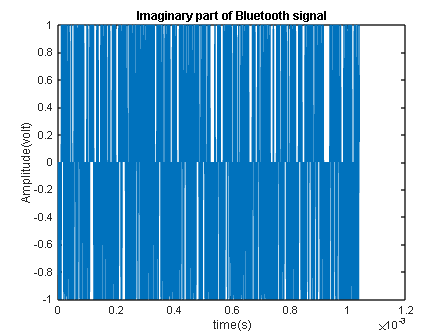

% plot imaginary part
plot(t, imag(signal))
title('Imaginary part of Bluetooth signal');
xlabel('time(s)');
ylabel('Amplitude(volt)');

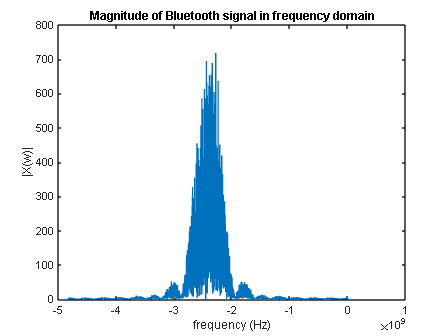

%frequecy parameter 
f = linspace(-fs_new/2, (fs/2)-(fs/length(signal)), length(t));

% plot imaginary part
plot(f, abs(fftshift(fft(signal))))
title('Magnitude of Bluetooth signal in frequency domain');
xlabel('frequency (Hz)');
ylabel('|X(w)|');

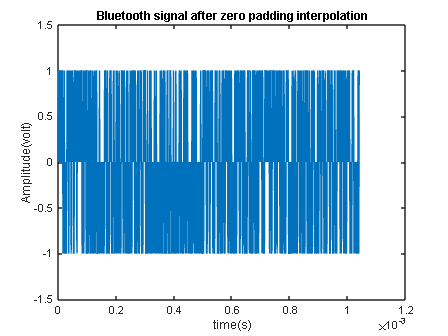

% intialization for parameters
fc = 2413000000; %MHz
Bw = 1000000; %Hz
fs_new = 2*(2*fc+Bw); %MHz

%Interpolation Filter

% first we need to upsample the signal

N = floor(fs_new/fs); %interpolation factor
F = fft(signal);                          % forward DFT
F = fftshift(F);                     % shift zero frequency to middle of array
m = length(F)*N-length(F);              % number for zero padding
F = [zeros(1,m/2),F.',zeros(1,m/2)];     % zero padding
F = ifftshift(F);                    % shift zero frequency back to first array element
interpolatedSamples = ifft(F) * length(F)/length(signal); 

%time parameter
t_new = linspace(0, total_time- (1/fs), length(interpolatedSamples));

% plot after interpolation
plot(t_new, real(interpolatedSamples));
title('Bluetooth signal after zero padding interpolation');
xlabel('time(s)');
ylabel('Amplitude(volt)');

% second we need to design lowpass filter
%Getting saved coefficient of the filter
Num = load("Num.mat").Num;
Hd = load("Hd.mat").Hd;

%Screenshot for filter settings

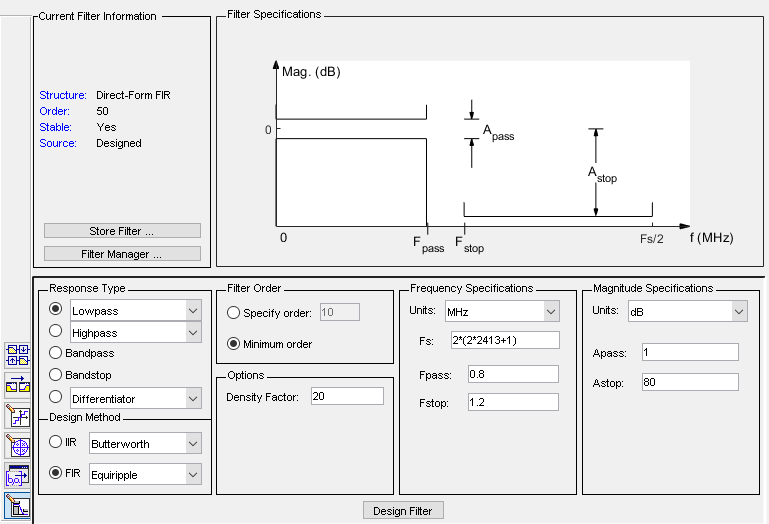

### Frequency response for the filter:

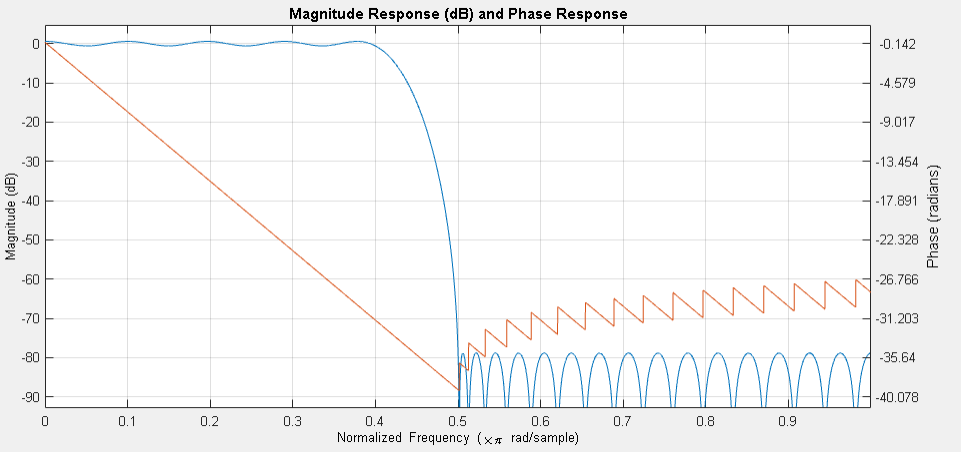

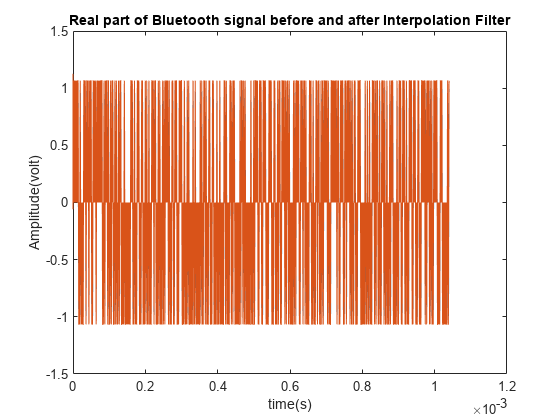

%Filter frequncy response
freqz(Hd);

%Filtering
filteredSignal = filter(Hd,interpolatedSamples);

%plot the generated signal vs the upsampled interpolated signal (baseband) on the same plot in time domain
%real part
plot(t, real(signal))
hold on
plot(t_new, real(filteredSignal))
title('Real part of Bluetooth signal before and after Interpolation Filter');
xlabel('time(s)');
ylabel('Amplitude(volt)');
hold off

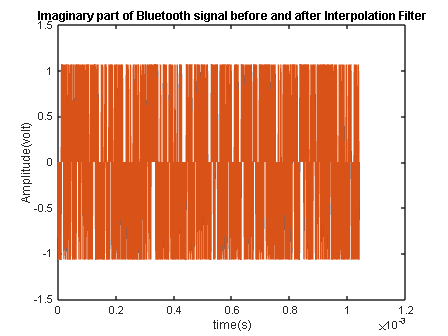


%imaginary part
plot(t, imag(signal))
hold on
plot(t_new, imag(filteredSignal))
title('Imaginary part of Bluetooth signal before and after Interpolation Filter');
xlabel('time(s)');
ylabel('Amplitude(volt)');
hold off

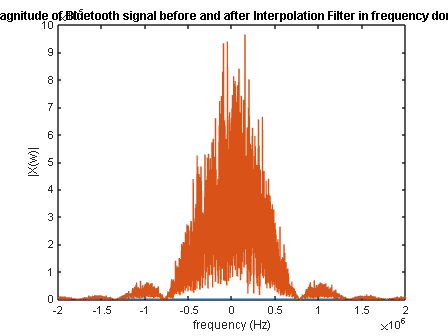

%plot the generated signal vs the upsampled interpolated signal (baseband) on the same plot in frequency domain
f_new = linspace(-fs_new/2, (fs_new/2)-(fs_new/length(filteredSignal)), length(t_new));

fft_signal = fftshift(fft(signal));
fft_filtered = fftshift(fft(filteredSignal));

%magnitude only
plot(f, abs(fft_signal));
hold on 
plot(f_new, abs(fft_filtered));
xlim([-2e6, 2e6])
title('Magnitude of Bluetooth signal before and after Interpolation Filter in frequency domain');
xlabel('frequency (Hz)');
ylabel('|X(w)|');
hold off

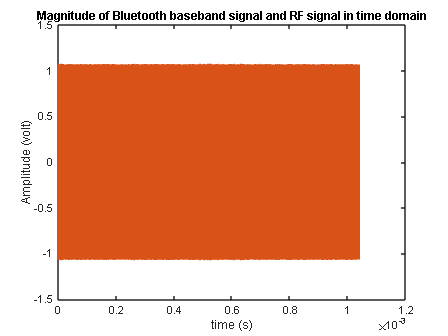

%Digital Mixer

%Carrier
w = 2*pi*fc; 

wt = w*t_new;

RF_signal = real(filteredSignal).*cos(wt) + imag(filteredSignal).*sin(wt);

%plot the baseband vs RF signal in the time domain
plot(t, abs(signal))
hold on
plot(t_new, RF_signal)
title('Magnitude of Bluetooth baseband signal and RF signal in time domain');
xlabel('time (s)');
ylabel('Amplitude (volt)');
hold off

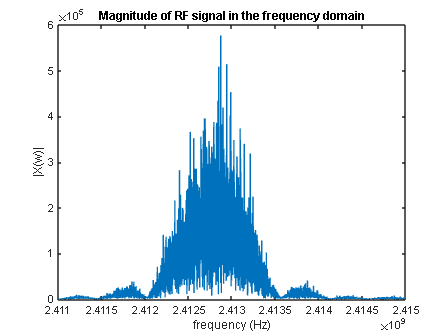

%plot the RF signal in the frequency domain
plot(f_new, abs(fft(RF_signal)))
title('Magnitude of RF signal in the frequency domain');
xlabel('frequency (Hz)');
ylabel('|X(w)|');
xlim([fc-2e6, fc+2e6])

## Channel

%Adding AWGN noise
noisy_signal = awgn(RF_signal,100,'measured'); %SNR = 100

## SDR Receiver

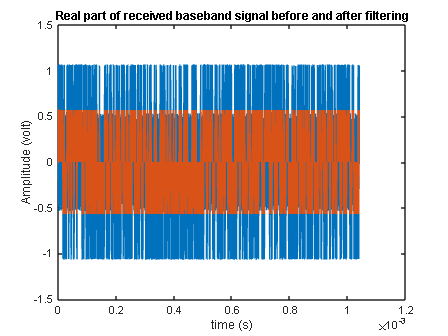

%Digital mixer
recieved_signal_real = noisy_signal.*cos(wt);
recieved_signal_img = noisy_signal.*sin(wt);

%Filtering
recieved_filtered_signal_real = filter(Hd,recieved_signal_real);
recieved_filtered_signal_img = filter(Hd,recieved_signal_img);

% plot the Received baseband signal before and after filtering
% real part
plot(t_new, recieved_signal_real)
hold on 
title('Real part of received baseband signal before and after filtering');
xlabel('time (s)');
ylabel('Amplitude (volt)');
plot(t_new, recieved_filtered_signal_real)
hold off

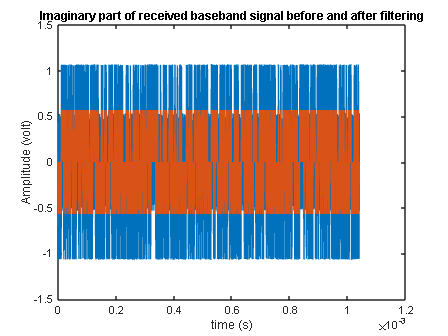

% imaginary part
plot(t_new, recieved_signal_img)
hold on 
title('Imaginary part of received baseband signal before and after filtering');
xlabel('time (s)');
ylabel('Amplitude (volt)');
plot(t_new, recieved_filtered_signal_img)
hold off

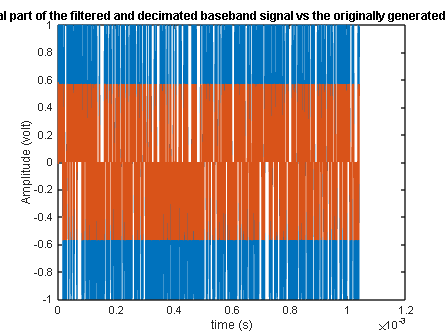

%downsampling
downsampled_signal_img = recieved_filtered_signal_img(1:N:length(recieved_filtered_signal_img));
downsampled_signal_real = recieved_filtered_signal_real(1:N:length(recieved_filtered_signal_real));

%Plot the filtered and decimated baseband signal vs the originally generated signal
% real part
plot(t, real(signal))
hold on
title('Real part of the filtered and decimated baseband signal vs the originally generated signal');
xlabel('time (s)');
ylabel('Amplitude (volt)');
plot(t_new, recieved_filtered_signal_real)
hold off

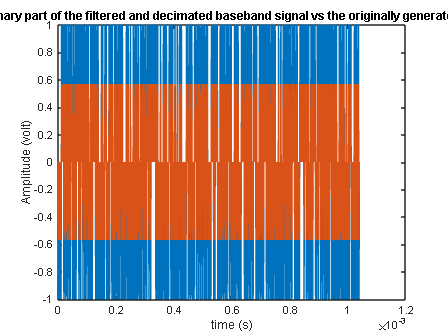

% imaginary part
plot(t, imag(signal))
hold on
title('Imaginary part of the filtered and decimated baseband signal vs the originally generated signal');
xlabel('time (s)');
ylabel('Amplitude (volt)');
plot(t_new, recieved_filtered_signal_img)
hold off

### Comments:

- Bandwidth is noticed from the graph of Bluetooth Signal.

- The upsampling frequency fs is choosen to be 2*(2*fc+Bw) for the following reseasons:

                1. It is integer multiple of fc and bandwidth to ensure that the upsampled signal has a consistant sample rate and can be easily processed.

                2. It is large enough to ensure that the upsampled signal contains all the information in the original baseband signal (following nyquist theorem).

                3. The highest frequency component is (2*fc + Bw) so the fs should be at least twice this value.

                4. The signal is multiplied by the carrier twice, one to shift the frequency of baseband signal to RF frequency, and the other when we recieved the signal to return it to baseband.

- fc is choosen according to our group number.

- We have tried to implement trigonometric interpolation filter, but it gives wrong results so we used zero padding interpolation.

### Trigonometric Interpolation Filter:

function interpolatedSamples = trigInterpolationFilter(digitalBasebandSamples)

%calculate the frequency of the signal
freqs = fft(digitalBasebandSamples);

%get number of samples
n = length(digitalBasebandSamples);

%calculate coefficients
a = zeros(1, n);
b = zeros(1, n);
for i = 1:n
    a(i) = digitalBasebandSamples(i)*sin(2*pi*freqs(i));
    b(i) = digitalBasebandSamples(i)*sin(2*pi*freqs(i));
end

%interpolate samples 
interpolatedSamples = @(t) sum(a.*sin(2*pi*freqs*t)) + sum(b.*cos(2*pi*freqs*t));

end

## Bluetooth Low Energy Generator:

function [waveform,Fs] = generateBLEWaveform(sps)
%% Generating Bluetooth Low Energy waveform
% Bluetooth Low Energy configuration
% sps = 1;
symbolRate = 1000000;
% input bit source:
in = randi([0, 1], 1000, 1);


% Generation
waveform = bleWaveformGenerator(in, 'Mode', 'LE1M', ...
    'SamplesPerSymbol', sps, ...
    'ChannelIndex', 37, ...
    'AccessAddress', [0 1 1 0 1 0 1 1 0 1 1 1 1 1 0 1 1 0 0 1 0 0 0 1 0 1 1 1 0 0 0 1]');

Fs = sps * symbolRate; 

end